# **Part 1**

Clear the workspace and close all figure windows

clear all
close all
clc

Load the data for this question

load Q1data.mat

## **a) random initialization by sampling components using a uniform distribution for each component on the interval [-1.2, 1.2] **

Set the number of data vectors (n) and the dimension of the data space (m)

[n,m] = size(XData);

Set the number of clusters (k)

k=5;

Assign each data vector, randomly to one of the k clusters

IndexSet = randi(k,n,1);

Plot the data

scatter(XData(:,1),XData(:,2),64,IndexSet,'filled');
hold on

Create data structures to store the weight vectors for cluster (c), and the weight vectors from the previous iteration (cPrev)

c = zeros(k,m);
cPrev = zeros(k,m);

Randomly initialize the weight vectors so that each component is sampled from the interval [-1.2,1.2]

c = -1.2 + 2.4*rand(k,m);

Plot the initial weight vectors

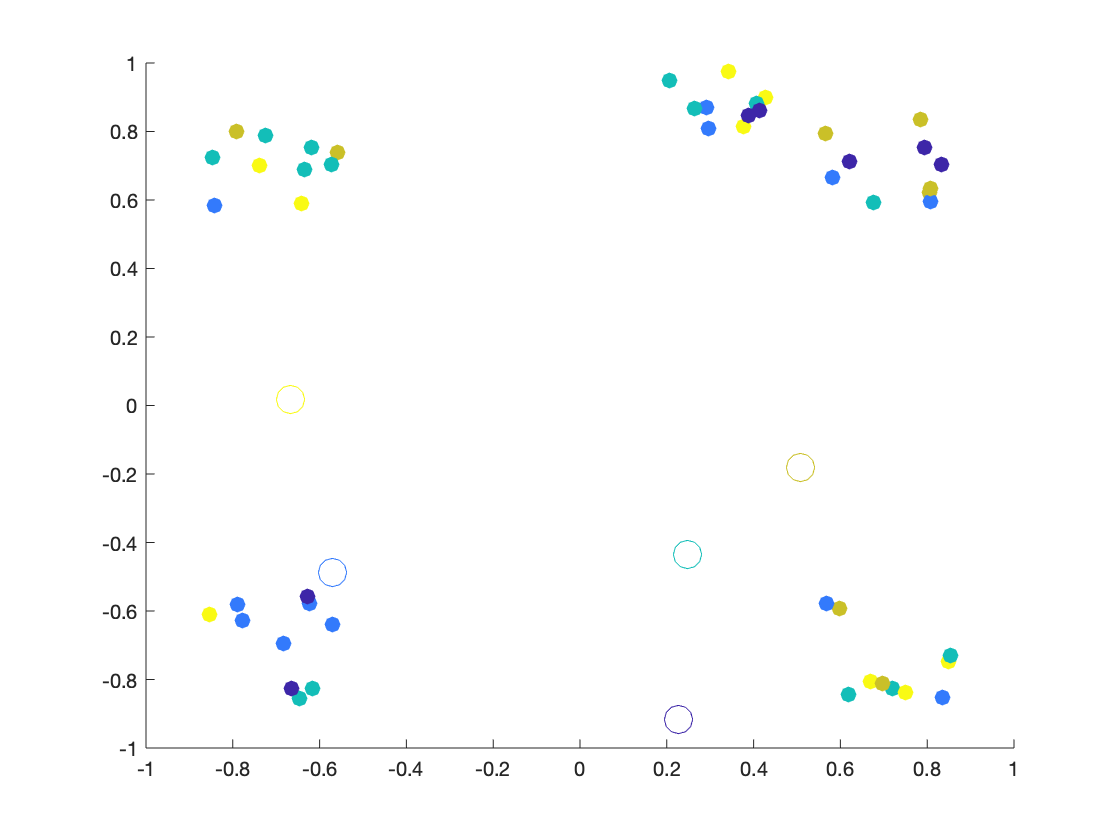

scatter(c(:,1),c(:,2),200,linspace(1,k,k))
hold off
pause

### **The Alternating Minimization Scheme**

doneFlag=0;

Keep alternating updates to weight vectors and cluster assignments until weight vectors no longer change their locations

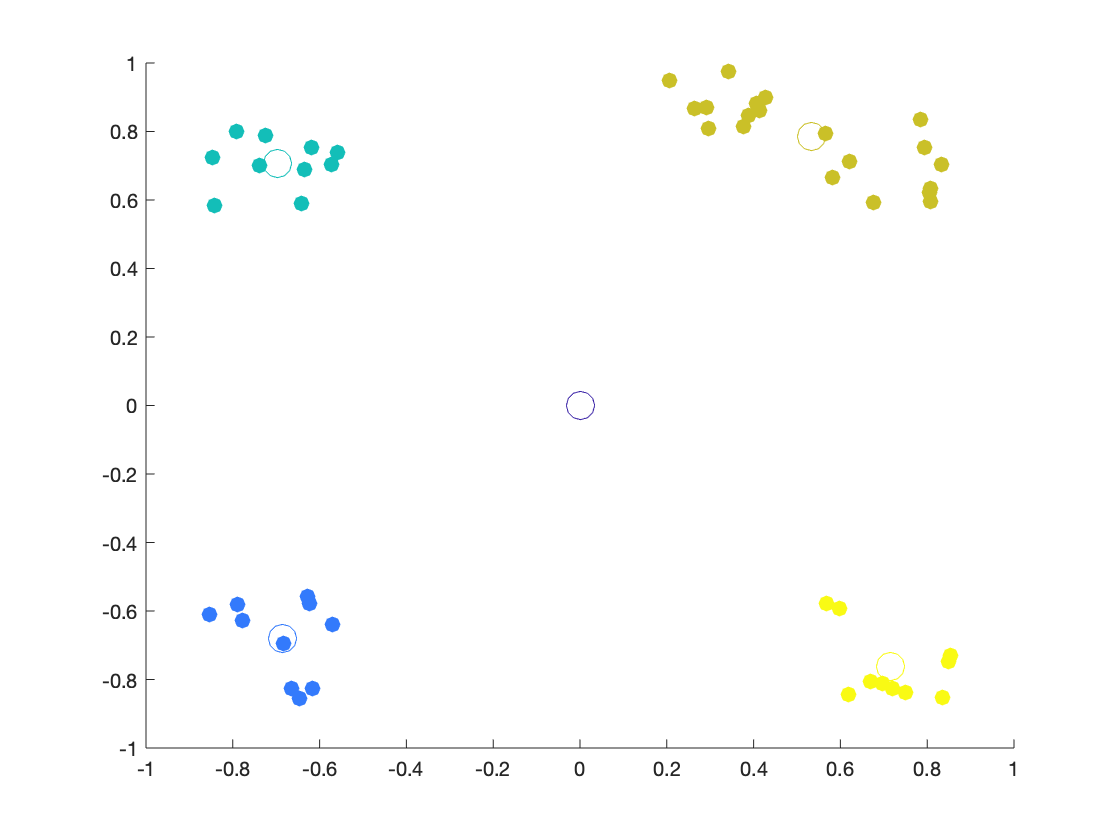

while (~doneFlag)

    % Update the weight vectors in each cluster via the centroid formula
    for i=1:k 

        % Find the indices for all data vectors currently in cluster i
        ClusterIndices = find(IndexSet==i);

        % Find the number of data vectors currently in cluster i
        NumVecsInCluster = size(ClusterIndices,1);

        % Create a data structure to store weight vector for the current
        % cluster
        c(i,:)=0; 

        % Update cluster vector using the centroid formula
        for j=1:NumVecsInCluster
            for l=1:m
                c(i,l) = c(i,l) + XData(ClusterIndices(j,1),l)/NumVecsInCluster;
            end
        end

    end

    % Plot the updated weight vectors for each cluster
    scatter(XData(:,1),XData(:,2),64,IndexSet,'filled')
    hold on
    scatter(c(:,1),c(:,2),200,linspace(1,k,k))
    pause
    
    % Now reassign all data vectors to the closest weight vector (cluster)

    % Create a data structure to store closest weight vector for each data
    % point
    closestCluster=zeros(n,1);

    % Reassign each data vector to the new, closest cluster
    for d=1:n

        % Store the coordinates of the current data vector
        xD = XData(d,:);

        % Set the minimum distance tracker to be a very large number
        sqDistMin=1e16;

        % Find the closest weight vector (cluster) to the current data
        % vector
        for i=1:k
            sqDist = norm(c(i,:)-xD,2);

            % If the distance is less than the current min, assign the
            % current data vector to this cluster
            if sqDist<sqDistMin
                closestCluster(d)=i;
                sqDistMin=sqDist;
            end

        end
    end

    % Update the assignments of the data vectors to their new clusters
    IndexSet = closestCluster;
    
    % Plot the data and the updated weight vectors
    hold off
    scatter(XData(:,1),XData(:,2),64,IndexSet,'filled')
    hold on
    scatter(c(:,1),c(:,2),200,linspace(1,k,k))
    hold off
    pause
    
    % Terminate the alternating scheme if the weight vectors are unaltered
    % relative to the previous iteration
    if c==cPrev
        doneFlag=1;
    else
        cPrev=c;
    end
end

## b) the k++ initialization outlined in the project instructions

Reintroduce necessary information

[n,m] = size(XData);
data = XData;
k = 5;
IndexSet = randi(k,n,1);

Initialize a vector to hold the c vectors for when the initialization is complete

c_values = zeros(k,m);

Randomly select one of the points in the data set and assign it as the initial value of the representatitve vector c1

randIndex = randi(n);

Update c_values with c1

c_values(1,:) = data(randIndex,:);

Remove c1 from the data so that it cannot be reselected

data(randIndex,:) = [];